% Name: Ziyi Xu
% Student ID: 20705396 
% Email: z297xu@uwaterloo.ca

## Question 1

% Reference: https://www.geeksforgeeks.org/extract-bit-planes-image-matlab/
% Read the image
img = imread('slope.tif');

% Storing image information in img2
img2 = double(img);


### Figure 1 - Show the upper 4 bitplanes in 4 sub-figures 

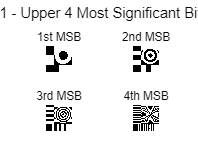

figure(2);

% Use mod to find 8 different significant bitplane
% b1 is the most significant bitplane, and so on
b4 = mod(floor(img2/(pow2(4))),2);
b3 = mod(floor(img2/(pow2(5))),2);
b2 = mod(floor(img2/(pow2(6))),2);
b1 = mod(floor(img2/(pow2(7))),2);

% Plot each upper 4 most significant bitplanes
subplot(2,2,1);
imshow(b1);
title('1st MSB');

subplot(2,2,2);
imshow(b2);
title('2nd MSB');

subplot(2,2,3);
imshow(b3);
title('3rd MSB');

subplot(2,2,4);
imshow(b4);
title('4th MSB');

sgtitle('Figure 1 - Upper 4 Most Significant Bitplanes');

### Figure 2  - Show the lower 4 bitplanes

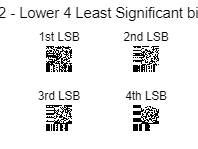

figure(3);

% Use mod to find 8 different significant bitplane
% b8 is the least significant bitplane, and so on
b8 = mod(floor(img2/(pow2(0))),2);
b7 = mod(floor(img2/(pow2(1))),2);
b6 = mod(floor(img2/(pow2(2))),2);
b5 = mod(floor(img2/(pow2(3))),2);

subplot(2,2,1);
imshow(b8);
title('1st LSB');

subplot(2,2,2);
imshow(b7);
title('2nd LSB');

subplot(2,2,3);
imshow(b6);
title('3rd LSB');

subplot(2,2,4);
imshow(b5);
title('4th LSB');

sgtitle('Figure 2 - Lower 4 Least Significant bitplanes');

### Figure 3 - Reconstructed Images using the Upper 1, 2, 3 and 4 bitplanes

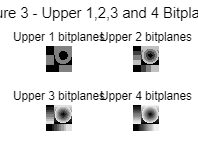

figure(4);

r1 = b1 * pow2(7);
r2 = r1 + b2 * pow2(6);
r3 = r2 + b3 * pow2(5);
r4 = r3 + b4 * pow2(4);

subplot(2,2,1);
imshow(uint8(r1));
title('Upper 1 bitplanes');

subplot(2,2,2);
imshow(uint8(r2));
title('Upper 2 bitplanes');

subplot(2,2,3);
imshow(uint8(r3));
title('Upper 3 bitplanes');

subplot(2,2,4);
imshow(uint8(r4));
title('Upper 4 bitplanes');

sgtitle('Figure 3 - Upper 1,2,3 and 4 Bitplanes');

### Figure 4 - Reconstructed Images by Using the Upper 5, 6, 7 and 8 Bitplanes

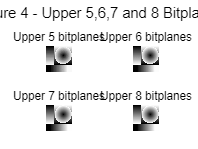

figure(5);

r5 = r4 + b5 * pow2(3);
r6 = r5 + b6 * pow2(2);
r7 = r6 + b7 * pow2(1);
r8 = r7 + b8 * pow2(0);

subplot(2,2,1);
imshow(uint8(r5));
title('Upper 5 bitplanes');

subplot(2,2,2);
imshow(uint8(r6));
title('Upper 6 bitplanes');

subplot(2,2,3);
imshow(uint8(r7));
title('Upper 7 bitplanes');

subplot(2,2,4);
imshow(uint8(r8));
title('Upper 8 bitplanes');

sgtitle('Figure 4 - Upper 5,6,7 and 8 Bitplanes');

### Observations

Based on the results from 4 figures shown above, we can observe that with increasing numbers of upper bitplanes (from using the most significant bitplane only to using all 8 bitplanes), the reconstructed images are more and more similar to the original image. Specially, the reconstruced image using all bitplanes is almost the same as the original image. 

## Question 2: Intensity Transformations

### 2.1 Gamma Mapping

clear;
img = imread('books.tif');
img = double(img);

% Normalize the image (Scale from [0-255] to [0,1])
scaleImg = img / 255;     

% Setup the Gamma
gamma_val = 0.5

gamma_val = 0.5000


gammaImg = scaleImg .^ gamma_val;

newImg = round(gammaImg .* 255);

### 2.2 Full-Scale Contrast Strectch

% Find the minimum pixel of the image
r_min = min(img(:));
% Find the maximum pixel of the image
r_max = max(img(:));

newImg2 = round((255./(r_max-r_min)).*(img - r_min));

### **2.3 Histogram Equalization**

% Get the rows and columns of the image
[row,col] = size(img);

% Pre-set the histogram
p_hist = zeros(256,1);
newImg3 = zeros(row,col);

% Calculate the histogram
for i = 1 : row
    for j = 1 : col
        intensity = img(i,j);
        p_hist(intensity+1) = p_hist(intensity+1) + 1;
    end
end 

% Calculate the pdf
pdf = p_hist / (row * col);
        
% Calculate the cdf
cdf = cumsum(pdf);

% Get the histogram equalized image
for i = 1 : row
    for j = 1 : col
        newImg3(i,j) = round(cdf(img(i,j)+1) * 255);
    end
end

### 2.4 Figure 1 - Graphs Demostration

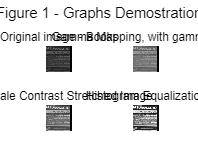

figure(6);
subplot(2,2,1);
imshow(uint8(img));
title("Original image - Books");

subplot(2,2,2);
imshow(uint8(newImg));
title("Gamma Mapping, with gamma = 0.5");

subplot(2,2,3);
imshow(uint8(newImg2));
title("Full-scale Contrast Stretched Image");

subplot(2,2,4);
imshow(uint8(newImg3));
title("Histogram Equalization");

sgtitle("Figure 1 - Graphs Demostration");

### 2.5 Figure 2 - Histogram for Each Graph

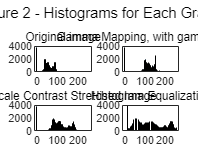

figure(7);
nbins = 256;
subplot(2,2,1);
histogram(img,0:255);
title("Original image");

subplot(2,2,2);
histogram(newImg,0:255);
title("Gamma Mapping, with gamma = 0.5");

subplot(2,2,3);
histogram(newImg2,0:255);
title("Full-scale Contrast Stretched Image");

subplot(2,2,4);
histogram(newImg3,0:255);
title("Histogram Equalization");

sgtitle("Figure 2 - Histograms for Each Graph");

### Observations:

Based on the result, we can observe that:

1) Gamma Mapping can change the overall brightness of the image. With gamma = 0.5, overall image becomes brigher than the original one.

2) Full-scale contrast stretched image can increase the contrast of the original image. From the resulted histogram (bottom-left), we can see that the full-scale contrast stretched image increases the difference between the maximum intensity and the minimum intensity in the original image. All of the rest intensities are "streched" out between the maximum and minimum intensities.

3) Histogram Equlized image can also increase the contrast of the original image. From tnhe resulted histogram (bottom-right), we can see that the histogram equalization wants to "flatten" the histogram into a uniform distribution.

4) Although full-scale contrast stretch and histogram equalization can increase the contrast, histogram equalizaion has a better result than full-scale contrast stretch, based on the results.

##  Question 3 - Frequency Domain Filtering

clear;
% Reference: https://www.cs.uregina.ca/Links/class-info/425/Lab5/index.html

img = imread('bridge.tif');
img = double(img);

### 3.1 Apply 2D-DFT

% Calculate 2D-DFT of the original image into frequency domain
F = fft2(img);

% Use the abs function to compute the magniture of the combined components,
% because there are real and imaginary parts to F
F_center = fftshift(F);

### 3.2 Apply the Ideal Lowpass Filters to the Frouier Transform of the image

% Define the lowpass filter
lowpassF = lowpassFilter(F_center, 1/8);
% Apply the lowpass filter to the frouier transform of the image
LPF_img_center = lowpassF.*F_center;
% Shift the result back
LPF_img_F = ifftshift(LPF_img_center);
% Calculate inverse 2D-DFT to get the image in spatial domain
LPF_img = real(ifft2(LPF_img_F));

### 3.3 Apply the Ideal Bandpass Filters to the Frouier Transform of the image

% Define the bandpass filter
bandpassF = bandpassFilter(F_center, 1/8, 1/2);
% Apply the bandpass filter to the frouier transform of the image
BPF_img_center = bandpassF.*F_center;
% Shift the result back
BPF_img_F = ifftshift(BPF_img_center);
% Calculate inverse 2D-DFT to get the image in spatial domain
BPF_img = real(ifft2(BPF_img_F));

### 3.4 Apply the Ideal Highpass Filters to the Frouier Transform of the image

% Define the highpass filter
highpassF = highpassFilter(F_center, 1/2);
% Apply the bandpass filter to the frouier transform of the image
HPF_img_center = highpassF.*F_center;
% Shift the result back
HPF_img_F = ifftshift(HPF_img_center);
% Calculate inverse 2D-DFT to get the image in spatial domain
HPF_img = real(ifft2(HPF_img_F));

### 3.5 Figure 1 - Images in the Spatial Domain

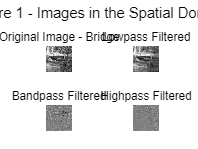

figure(8);
subplot(2,2,1);
imshow(uint8(img));
title("Original Image - Bridge");

subplot(2,2,2);
imshow(uint8(LPF_img));
title("Lowpass Filtered");

subplot(2,2,3);
% Add 128 to all pixels so that the negative values 
% are darker than the mid-gray and the positive values
% are brighter than the mid-gray
imshow(uint8((BPF_img + 128)));
title("Bandpass Filtered");

subplot(2,2,4);
imshow(uint8((HPF_img + 128)));
title("Highpass Filtered");

sgtitle("Figure 1 - Images in the Spatial Domain");

### 3.6 Figure 2 - Amplitude Spectra of Each Image

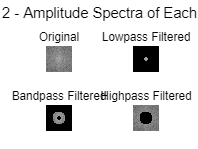

figure(9);
subplot(2,2,1);
F_c = log(1+abs(F_center));
% Find the brightest point in the frequency domain
r_max = max(F_c(:));
r_min = 0;
% Do the normalization so that the brightest white point
% maps to the brightest value 1 and all other values are 
% between 0 and 1
F_norm = (F_c / r_max);
imshow(F_norm);
title("Original");

subplot(2,2,2);
LPF_c = log(1+abs(LPF_img_center));
LPF_norm = (1./(r_max-r_min)).*(LPF_c - r_min);
imshow(LPF_norm);
title("Lowpass Filtered");

subplot(2,2,3);
BPF_c = log(1+abs(BPF_img_center));
BPF_norm = (1./(r_max-r_min)).*(BPF_c - r_min); 
imshow(BPF_norm);
title("Bandpass Filtered");

subplot(2,2,4);
HPF_c = log(1+abs(HPF_img_center));
HPF_norm = (1./(r_max-r_min)).*(HPF_c - r_min); 
imshow(HPF_norm);
title("Highpass Filtered");

sgtitle("Figure 2 - Amplitude Spectra of Each Image")

### Observations:

Because we shifted the frequency domain, most important information are concentrated around the center point, and other less important information are away from the center point. 

1) The lowpass filtered image is blurred than the original one. The possible reason is that lowpass filter keep the center part in the frequency spectra, which means it keep most important information of the original image. But the lowpass filter blocks other less important information as well, so the filtered image is blurred compared to the original image.

2) The resulted image using bandpass filter can see the basic layout of the the object (i.e. bridge), however it is hard to recognize without the original image. It is possibly because the bandpass filter pass the information close to the center part but without the center part, which means it can still get some important information but not those most important information of the original image. Therefore the filtered image can still shows some features (i.e. some layouts of the bridge).

3) The highpass filtered image can only see some unclear edges of the object, which is very hard to recognize what the image is. It is because the highpass filter blocks all important information in the center and pass the least important information of the original image.

### Question 4 - Image Deblurring

### 4.1 Spatial Domain Gaussian Filter Creation

clear;

img = imread('text.tif');

gf = zeros(21,21);
gf_row = 21;
gf_col = 21;
center = round(gf_row/2);

% Do the normalized Gaussian Filter
sigma = 1;
for i = 1:21
    for j = 1:21
        gf(i,j) = (1/(2*pi*sigma^2))*exp(-((i-center)^2+(j-center)^2)/(2*sigma^2));
    end
end
gf = gf./sum(gf(:));

### 4.2 Blurred Image

% Make a convolution between image and Gaussian Filter
ConvImg = conv2(img,gf);
[row1,col1] = size(ConvImg);

% Crop the central part of the image
cropImg1 = ConvImg(row1/2 - 127:row1/2 + 128, col1 / 2 - 127: col1 / 2 + 128);

### 4.3 Apply 2D-DFT and Inverse 2D-DFT of the Gaussian Filter

% Change Gaussian Filter into the frequency domain
gauss_F = fft2(gf);
% Take the reciprocal value of all frequency domain Gaussian Filter
% Coefficients
gauss_F_reci = 1./gauss_F;

% Do the inverse 2D-DFT of the Gaussian Filter in frequency domain
gf_inv = real(ifft2(gauss_F_reci));

### 4.4 Deblurred Image

ConvImg2 = conv2(ConvImg, gf_inv);
[row2,col2] = size(ConvImg2);

cropImg2 = ConvImg2(row2/2 - 127:row2/2 + 128, col2 / 2 - 127: col2 / 2 + 128);

### 4.5 Figure 1 - Demostration

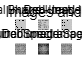

figure(10);
subplot(2,3,1);
imshow(img);
title("Origial Image - text");

subplot(2,3,2);
imshow(uint8(cropImg1));
title("Blurred Image");

subplot(2,3,3);
imshow(uint8(cropImg2));
title("Deblurred Image");

% Calculate 2D-DFT of the original image into frequency domain
subplot(2,3,4);
F = fft2(img);
F_center = fftshift(F);
F_c = log(1+abs(F_center));
% Find the brightest point in the frequency domain
r_max = max(F_c,[],'all');
r_min = 0;
F_norm = (1./(r_max-r_min)).*(F_c - r_min);
imshow(F_norm);
title("Original Spectra");

subplot(2,3,5);
crop1_F = fft2(cropImg1);
crop1_F_center = fftshift(crop1_F);
crop1_F_c = log(1+abs(crop1_F_center));
r_max = max(crop1_F_c,[],'all');
crop1_F_norm = (1./(r_max-r_min)).*(crop1_F_c - r_min);
imshow(crop1_F_norm);
title("Blurred Image Spectra");

subplot(2,3,6);
crop2_F = fft2(cropImg2);
crop2_F_center = fftshift(crop2_F);
crop2_F_c = log(1+abs(crop2_F_center));
r_max = max(crop2_F_c,[],'all');
crop2_F_norm = (1./(r_max-r_min)).*(crop2_F_c - r_min);
imshow(crop2_F_norm);
title("Deblurred Image Spectra");
sgtitle("Figure 1 - Images and Spectras");

### 4.6 Figure 2 - Magnitude Spectrum

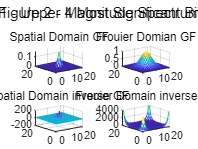

figure(11);
subplot(2,2,1);
mesh(gf);
title("Spatial Domain GF");

subplot(2,2,2);
mesh(abs(fftshift(gauss_F)));
title("Frouier Domian GF");

subplot(2,2,3);
mesh(gf_inv);
title("Spatial Domain inverse GF");

subplot(2,2,4);
mesh(abs(fftshift(gauss_F_reci)));
title("Frouier Domain inverse GF");

sgtitle("Figure 2 - Magnitude Spectrum");

**Observation**:

From the results between original image and deblurred image. In theory, these two images should be exactly same. However, when we see the deblurred image clearly, there are some light shadows in the deblurred image. 

## Question 5 - Image Interpolation

clear;

img = imread('einstein.tif');
img = double(img);
[row, col] = size(img);
factor = 3;

### 5.1 Downsample the Image

downSampled = downSample(img,factor);

### 5.2 Upsample the Image with Zero-Padding

upSampled = upSample(downSampled,row, col, factor);

### 5.3 Interpolated Image with Nearest Neighbor Method

mask3n = ones(1,factor);
nnImg_h = zeros(row, col);
nnImg = zeros(row,col);

for i = 1 : row
    nnImg_h(i,:) = conv(upSampled(i,:), mask3n, 'same');
end

for j = 1 : col
    nnImg(:,j) = conv(nnImg_h(:,j),mask3n, 'same');
end


### 5.4 Interpolated Image with Bilinear Interpolation Method

mask3b = BIM(factor);
bimImg_h = zeros(row,col);
bimImg = zeros(row,col);

for i = 1 : row
    bimImg_h(i,:) = conv(upSampled(i,:), mask3b, 'same');
end

for j = 1 : col
    bimImg(:,j) = conv(bimImg_h(:,j), mask3b, 'same');
end


### 5.5 Figure 1 - Demo for Case D = 3 

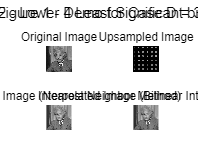

figure(12);
subplot(2,2,1);
imshow(img,[]);
title("Original Image");

subplot(2,2,2);
imshow(upSampled,[]);
title("Upsampled Image");

subplot(2,2,3);
imshow(nnImg,[]);
title("Interpolated Image (Nearest Neighbor Method)");

subplot(2,2,4);
imshow(bimImg, []);
title("Interpolated Image (Bilinear Interpolation)");

sgtitle("Figure 1 - Demo for Case D = 3");

### 5.6 Figure 2 - Deom for Case D = 7

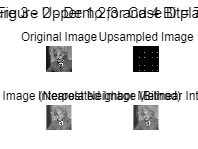

factor = 7;
% Downsample the original image
downSampled7 = downSample(img,factor);
% Upsample the downsampled iamge
upSampled7 = upSample(downSampled7,row, col, factor);

% Upsample by Nearest neighbor method
mask7n = ones(1,factor);
nnImg_h7 = zeros(row,col);
nnImg7 = zeros(row,col);

for i = 1 : row
    nnImg_h7(i,:) = conv(upSampled7(i,:),mask7n, 'same');
end

for j = 1 : col
    nnImg7(:,j) = conv(nnImg_h7(:,j),mask7n, 'same');
end

% Upsmaple by Biliniear Interpolation
mask7b = BIM(factor);
bimImg_h7 = zeros(row,col);
bimImg7 = zeros(row,col);

for i = 1 : row
    bimImg_h7(i,:) = conv(upSampled7(i,:),mask7b, 'same');
end

for j = 1 : col
    bimImg7(:,j) = conv(bimImg_h7(:,j),mask7b, 'same');
end

figure(13);
subplot(2,2,1);
imshow(img,[]);
title("Original Image");

subplot(2,2,2);
imshow(upSampled7,[]);
title("Upsampled Image");

subplot(2,2,3);
imshow(nnImg7,[]);
title("Interpolated Image (Nearest Neighbor Method)");

subplot(2,2,4);
imshow(bimImg7, []);
title("Interpolated Image (Bilinear Interpolation)");

sgtitle("Figure 2 - Demo for Case D = 7");

**Observation**:

1) With the increaing number of the factor D, the upsampled images become blurrer and blurrer.

2) Upsampled images using nearest neighbor interpolation make the image mosaic-styled, while the images using bilinear interpolation make the image much more smoother (still blurred) compared to the corresponding image using nearest neighbor interpolation.

### Function 1 -  Ideal Lowpass Filters Function

function filter = lowpassFilter(src, d0)
    [row, col] = size(src);
    row_center = row/2;
    col_center = col/2;
    d0 = row_center * d0;
    
    filter = zeros(row,col);
    for i = 1 : row
        for j = 1 : col
            dist = sqrt((i - row_center)^2 + (j - col_center)^2);
            if dist < d0
                filter(i,j) = 1;
            else
                filter(i,j) = 0;
            end
        end
    end
end

### Function 2 - Ideal Bandpass Filters Function

function filter = bandpassFilter(src, d0, d1)
    [row, col] = size(src);
    row_center = row/2;
    col_center = col/2;
    d0 = row_center * d0;
    d1 = row_center * d1;
    
    filter = zeros(row,col);
    for i = 1 : row
        for j = 1 : col
            dist = sqrt((i - row_center).^2 + (j - col_center).^2);
            if dist < d0
                filter(i,j) = 0;
            elseif dist > d1
                filter(i,j) = 0;
            else
                filter(i,j) = 1;
            end
        end
    end
end

### Function 3 -  Ideal Highpass Filters Function

function filter = highpassFilter(src, d1)
    [row, col] = size(src);
    row_center = row/2;
    col_center = col/2;
    d1 = row_center * d1; 
    
    filter = zeros(row,col);
    for i = 1 : row
        for j = 1 : col
            dist = sqrt((i - row_center).^2 + (j - col_center).^2);
            if dist <= d1
                filter(i,j) = 0;
            else
                filter(i,j) = 1;
            end
        end
    end
end

### Function 4 - Downsample Image Function

function resizeImg = downSample(src, factor)
    resizeImg = src((factor+1)/2:factor:end, (factor+1)/2:factor:end);
end 

### Function 5 - Upsample Image With Zero-Padding Function

function resizeImg = upSample(src, row, col ,factor)
    resizeImg = zeros(row,col);
    for i = 1 : row
        for j = 1 : col
            if (mod(i,factor) == 0 && mod(j,factor) == 0)
                resizeImg(i,j) = src(i/factor,j/factor);
            end
        end
    end 
end 


### Function 6 - Interpolation with Bilinear Interpolation Method Function

function mask_h = BIM(factor)
    mask_h = ones(1,2*factor-1);
    for i = factor - 1 : -1 : 1
        mask_h(1,i) = (1 - (1/factor) * (factor - i));
    end
    for i = factor + 1 : 2*factor-1
        mask_h(1,i) = (1 - (1/factor) * (i - factor));
    end
 
end